[v0, angle] = get_speed_and_angle(2,1,0)



% angle_range = [0:0.25:90]; % degrees
% count = 1;

% for i=angle_range
%     % convert from degrees to radians
% %     theta = i * (pi/180);
% 
%     % get v0y
%     v0y = v0x * tand(i);
%     angle_and_v0y(count,1) = i;
%     angle_and_v0y(count,2) = v0y;
%     count = count + 1;
% end
% 
% plot(angle_and_v0y(:,1),angle_and_v0y(:,2))

% input: time
% output: angle, speed 
speed0_root_lo = find_speed0(30) % input degrees, get speed
% check whether this works
% simulate ODE and see whether it hits

[T,M,did_hit_piano,end_time] = ode_penny(2.7668, 30);
did_hit_piano

% find angle associated with smallest difference in desired time and actual time


% for each speed and angle, determine if it will give the correct end x position
% at the point where it reaches y position of the piano (end the simulation at that point)

% after 90 degrees, it's not going to hit the piano no matter what
angle_range = [0:0.5:90]; % degrees
% 37.5 is the speed corresponding to 89.5 degrees
speed_range = [0:0.5:40]; % m/s
% there should one angle for each speed at which the pennies are shot
% that hits the piano (reaches the approximate distance of the x position)
count = 1;

for i=speed_range
    for j=angle_range
        % ode_penny parameters: (speed in m/s, angle in degrees)
        [T, M, did_hit_piano,end_time] = ode_penny(i,j);
        % sweep angle and speed; there should be one combination of each angle and
        % speed that will get did_hit_piano
        if did_hit_piano
%             uncomment to debug
%             i, j, end_time
            correct_angle_speed_combos(count, 1) = [i];
            correct_angle_speed_combos(count, 2) = [j];
            correct_angle_speed_combos(count, 3) = [end_time];
            count = count + 1;
        end
    end
end
correct_angle_speed_combos


notes_table = readtable("hot_cross_buns.csv", "Delimiter", ",")

notes_table = 17×2 table
    Length    Time
    ______    ____

      2          1
      2          2
      4          3
      2          5
      2          6
      4          7
      1          9
      1        9.5
      1         10
      1       10.5
      1         11
      1       11.5
      1         12
      1       12.5
      2         13
      2         14


notes_table.Time

ans =     1.0000
    2.0000
    3.0000
    5.0000
    6.0000
    7.0000
    9.0000
    9.5000
   10.0000
   10.5000



% calculate speed and angle needed to hit the piano at
% desired time, without drag
% this gives us the initial angle guess
[initial_speed_guess, angle] = get_speed_and_angle(desired_time,x_distance,y_distance)

initial_speed_guess = 5.0010

angle = 78.4654

% find the corresponding speed for this angle
speed0 = find_speed0(angle,initial_speed_guess) % input degrees, get speed

speed0 = 4.8658


% call ode_penny to get the time it takes to hit piano
% ode_penny parameters: (speed in m/s, angle in degrees)
[~,~,~,end_time] = ode_penny(angle,speed0);

% calculate error
error = abs(desired_time - end_time)

error = 0.3986

closest_angle = 83.5025

error = 2.8001e-06

% end time should be 1.0551
speed0 = find_speed0(79,5) % input degrees, get speed

error = -3.3307e-16

speed0 = 4.9828

x_distance = 1;
y_distance = 0;

% use root finding to get actual speed corresponding to angle with drag
initial_speed_guess = 100; % should pass in speed guess from get_speed_and_angle

% call ode_penny to get the time it takes to hit piano
% ode_penny parameters: (speed in m/s, angle in degrees)
[~,~,did_hit_piano,end_time] = ode_penny(speed0,79)

did_hit_piano = logical
   0


end_time = 1.4395


% calculate error
error = abs(desired_time - end_time);

% time_error(78.465)
[closest_angle, error] = find_closest_angle(25); % seconds
speed0 = find_speed0(closest_angle,100) % input degrees, get speed

speed0 = 122.4892


[T, M, did_hit_piano, end_time] = ode_penny(speed0,closest_angle);
% sweep angle and speed; there should be one combination of each angle and
% speed that will get did_hit_piano
did_hit_piano

did_hit_piano = logical
   1


end_time

end_time = 25.0001

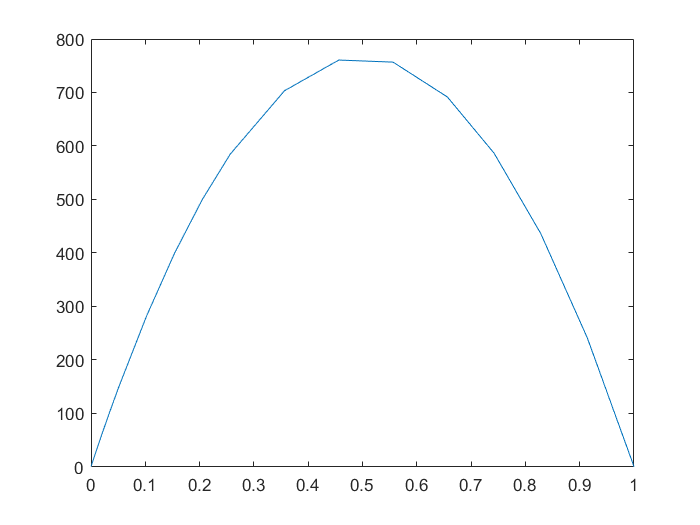

X = M(:,1);
Y = M(:,2);
plot(X, Y)

angle_range = [70:0.1:78.5]; % degrees
count = 1;
for i = angle_range
    X(count,1) = i;
    X(count,2) = time_error(i);
    count = count + 1;
end

error = 0.0154

error = 0.0121

error = 0.0088

error = 0.0054

error = 0.0020

error = 0.0014

error = 0.0048

error = 0.0083

error = 0.0117

error = 0.0152

error = 0.0188

error = 0.0223

error = 0.0259

error = 0.0296

error = 0.0332

error = 0.0369

error = 0.0406

error = 0.0443

error = 0.0481

error = 0.0519

error = 0.0557

error = 0.0596

error = 0.0635

error = 0.0674

error = 0.0714

error = 0.0754

error = 0.0794

error = 0.0835

error = 0.0876

error = 0.0917

error = 0.0959

error = 0.1001

error = 0.1043

error = 0.1086

error = 0.1129

error = 0.1173

error = 0.1216

error = 0.1261

error = 0.1306

error = 0.1351

error = 0.1396

error = 0.1442

error = 0.1489

error = 0.1535

error = 0.1583

error = 0.1631

error = 0.1679

error = 0.1727

error = 0.1776

error = 0.1826

error = 0.1876

error = 0.1927

error = 0.1978

error = 0.2029

error = 0.2082

error = 0.2134

error = 0.2187

error = 0.2241

error = 0.2295

error = 0.2350

error = 0.2406

error = 0.2462

error = 0.2518

error = 0.2575

error = 0.2633

error = 0.2692

error = 0.2751

error = 0.2810

error = 0.2871

error = 0.2932

error = 0.2993

error = 0.3056

error = 0.3119

error = 0.3183

error = 0.3247

error = 0.3313

error = 0.3379

error = 0.3446

error = 0.3514

error = 0.3582

error = 0.3651

error = 0.3722

error = 0.3793

error = 0.3865

error = 0.3938

error = 0.4011

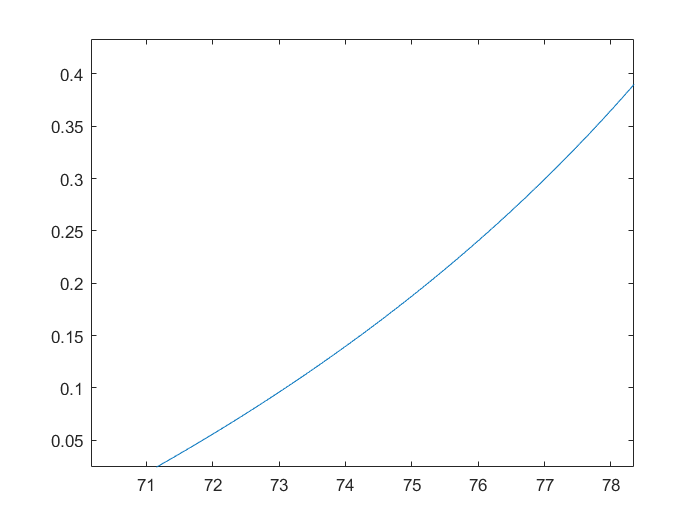

Not enough input arguments.

Error in time_error (line 9)
     if angle >= 90 || angle < 0

Error in fminsearch (line 201)
fv(:,1) = funfcn(x,varargin{:});

ans = 1000000

error = 0.1381

ans = 0.1381

ans = 1000000

ans = 1000000

plot(X(:,1),X(:,2))

error = 0.3986

error = 0.7889

error = 0.1651

error = 0.0054

error = 0.2035

error = 0.1123

error = 0.1651

error = 0.0575

error = 0.0786

error = 0.0271

error = 0.0406

error = 0.0111

error = 0.0227

error = 0.0029

error = 0.0111

error = 0.0012

error = 0.0054

error = 8.4525e-04

error = 0.0029

error = 1.9775e-04

error = 0.0012

error = 3.2406e-04

error = 7.2016e-04

error = 6.3230e-05

error = 3.2406e-04

error = 6.7240e-05

error = 1.9366e-04

error = 2.0001e-06

error = 6.7240e-05

error = 3.0616e-05

error = 3.4619e-05

error = 1.4308e-05

error = 1.8309e-05

error = 6.1542e-06

error = 1.0155e-05

error = 2.0770e-06

error = 6.0773e-06

error = 3.8468e-08

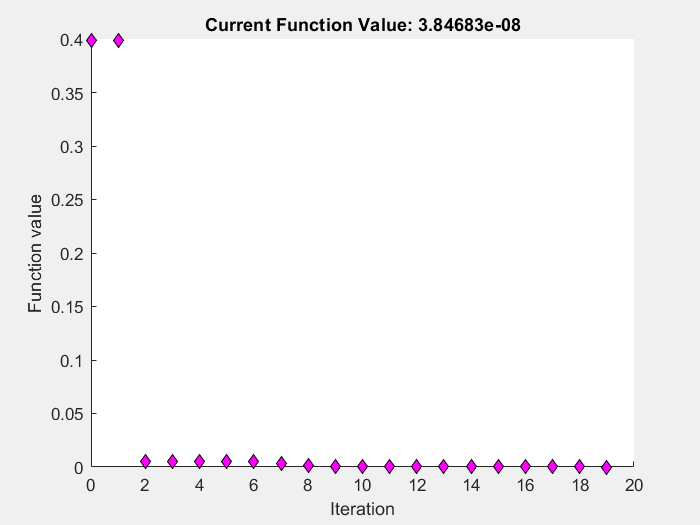

angle = 70.4598

fval = 3.8468e-08


options = optimset('PlotFcns',@optimplotfval);
[angle, fval] = fminsearch(@time_error, angle, options)

% it's not working because fminsearch is stupid and is using values above
% 90, maybe
% time_error(angle)
% time_error(84)


speed0 = 9.7444

speed0 = 10.2358

speed0 = 10.7273

speed0 = 11.2188

speed0 = 12.2017

speed0 = 13.1843

speed0 = 15.1491

speed0 = 17.1131

speed0 = 21.0392

speed0 = 24.9637

speed0 = 32.8098

speed0 = 40.6536

speed0 = 40.6536

speed0 = 28.8871

speed0 = 36.7318

speed0 = 30.8485

speed0 = 34.7709

speed0 = 31.8292

speed0 = 33.7903

speed0 = 32.3195

speed0 = 33.3000

speed0 = 33.0549

speed0 = 33.3000

speed0 = 32.9323

speed0 = 33.1775

speed0 = 32.9936

speed0 = 33.1162

speed0 = 33.0243

speed0 = 33.0855

speed0 = 33.0702

speed0 = 33.0855

speed0 = 33.0626

speed0 = 33.0779

speed0 = 33.0664

speed0 = 33.0741

speed0 = 33.0683

speed0 = 33.0721

speed0 = 33.0741

speed0 = 33.0741

speed0 = 33.0712

speed0 = 33.0731

speed0 = 33.0717

ans = 6.7534

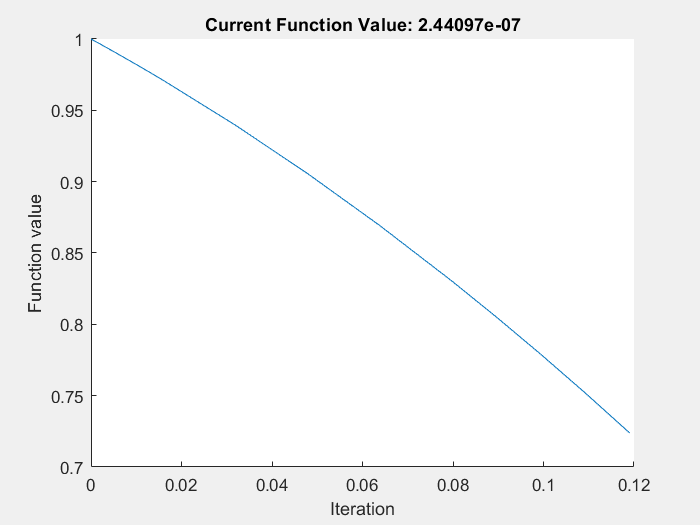

[T, M, ~,~] = ode_penny(10,-10);
plot(T,M(:,2))

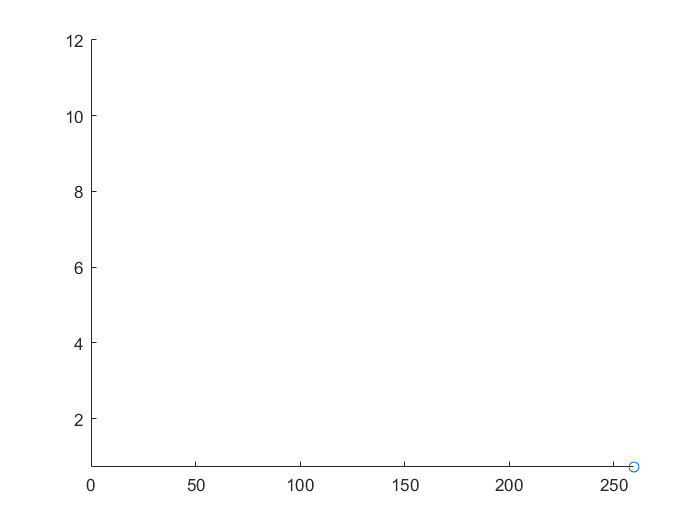

animate(T,M)

function animate(T, M)
    X = M(:,1);
    Y = M(:,2);
    minmax = [min([X]),max([X]),min([Y]),max([Y])];
    
    for i=1:length(T)
        clf; hold on
        axis(minmax)
        plot(X(i),Y(i),'o')
        drawnow;
        
        if i < length (T)
            dt = T(i+1) - T(i);
            pause(dt);
        end
    end
end